# Demo

## Direction of Arrival Estimation with a Uniform Linear Array in Compressed Beamforming Application.

This is a simple demo on how to use `saen-clarsen MATLAB package` in compressed beamforming (CBF) for single-snapshot direction of arrival (DoA) estimation. It can be done by following steps.

Firstly, generate the design matrix (i.e., dictionary) **X** for `"p"` possible look directions (angles) using a uniform linear array (ULA) composed of `"n"` sensor elements. The ULA has an inter-element spacing of half a wavelength.

% Code by Muhammad Naveed Tabassum and Esa Ollila, Aalto University. <2018>
clearvars;  close all hidden;   clc;
rng(920)
p = 30; % possible look directions       
n = 10; % #of Sensors in ULA
TH_deg = 180*(0:p-1)/p - 90;   
X = (1/sqrt(n)) * exp( 1i*pi*(0:n-1)'*sin(deg2rad(TH_deg)) );
sdX = sqrt( sum(X.*conj(X)) );
X = bsxfun(@rdivide, X, sdX);


At ULA, record a snapshot of `noisy observations` as a vector **y **for the wavefield incident on the ULA. This can be done for `"K"` sources having some random powers and DoAs, as:

K = 3;
srcPow = 0.4 + 0.6*rand(K,1);       srcPow = round(srcPow/max(srcPow),1);
srcLoc = TH_deg(randperm(p,K));
sigVar = sum(srcPow.^2) / K; % signal variance = average source power = (|s1|^2+|s2|^2+...+|sK|^2)/K
SNRdB = 20;
noiseVar = 10^(-0.1*SNRdB)*sigVar; % noise variance based on SNR-level in dB.

[~, srcIndx] = ismember(srcLoc, TH_deg);
Xs = X(:,srcIndx);
srcTrueK = srcPow.*exp(1i*unifrnd(0,2*pi, [K 1])); 	% signal = |s|exp(j*U(0,2*pi))
cscg_noise = sqrt(noiseVar/2)*(randn(n, 1) + 1i*randn(n, 1));	% circularly symmetric complex gaussian (CSCG) noise
y = Xs*srcTrueK + cscg_noise;  % Noisy observations
srcTruth = zeros(p,1);
srcTruth(srcIndx) = srcTrueK; % Underlying true model in complex domain


Next, the SAEN approach estimates the DoAs using c-PW-WEN and c-LARS-WLasso algorithms. 

m = 10;
AL = linspace(1,1e-1, m);  % Grid of elastic net tunning parameter with 'm' values.
tic
[betaK] = saen(y,X,K,AL);
elapsedTime = toc

elapsedTime = 0.4173

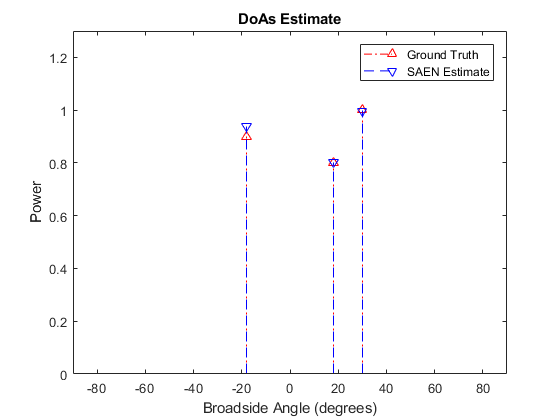


% Plotting
clf, figure(1);
srcTruth(srcTruth==0) = nan;    betaK(betaK==0) = nan;
stem(TH_deg, abs(srcTruth),'-.r^');     hold on;
stem(TH_deg, abs(betaK),'--bv');        hold off;
axis([-90,90, 0,1.3]);
xlabel('Broadside Angle (degrees)');    ylabel('Power');
title('DoAs Estimate')
legend('Ground Truth', 'SAEN Estimate');